# Trabalho 8A Parte 1 - Identificação paramétrica de servomecanismos de velocidade

#### Loading the data into matlab's environment.

data = load("data_aula8.mat"); 
data = data.data_aula8;

## a)  Verificar se a dinâmica real pode se aproximar a um sistema de segunda ordem.

-     `data.Y.(1) -> Reference angular velocity`

- `    data.Y.(2) -> Encoder readings`

- `    data.Y.(3) -> Real angular velocity readinds`

- `    data.Y.(4) -> Encoder readings as well? `   

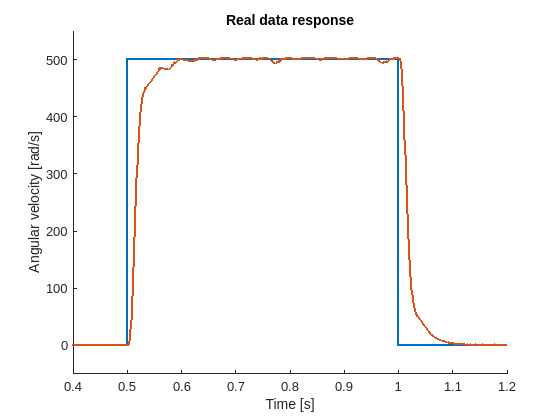

time_data = data.X.Data; % 1x2501 double
w_ref = double(data.Y(1).Data);
w_real = double(data.Y(3).Data);

hold on;
plot(time_data,w_ref,LineWidth=2)
plot(time_data,w_real,LineWidth=2)
hold off;
ylabel("Angular velocity [rad/s]")
xlabel("Time [s]")
title("Real data response")
xlim([0.4 1.2])
ylim([-50 550])

The real angular velocity dynamic can be approximated by a 2ºorder system:

Even though the first maximum isn't the peak value, if you can abstract from the noise, by applying a smoothing function, the curve approximates a second order system well.

However the same can't be said for a first order system, as besides the noise, there is some clear oscillation, which isn't allowed by a first order system.

This hypothesis will be further analysed in the points i through iv.

### i) Using then lsim Matlab function

The transfer function is of the following form:


$$\frac{\mathit{\mathbf{k}}}{\left(\mathit{\mathbf{s}}+{\mathit{\mathbf{p}}}_1 \right)\left(\mathit{\mathbf{s}}+{\mathit{\mathbf{p}}}_{2\;} \right)}$$
 

Here we are assuming both poles are more or less equal, so that there is only 1 variable to control.

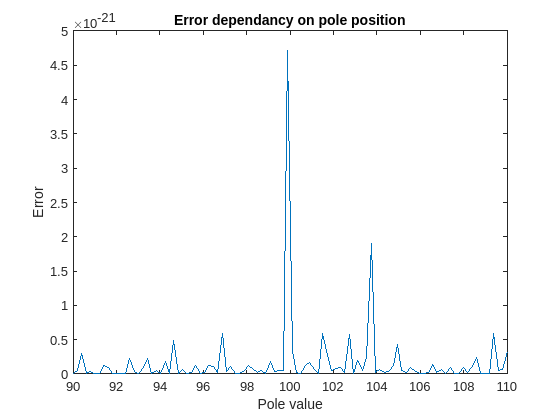


s = tf('s');
error = [];
pvec = linspace(90,110,100);

for i=1:length(pvec)
    p = pvec(i);
    k = p^2;
    G = k/(s+p)^2;
    y = lsim(G,w_ref,time_data);
    error = [error sum(y-w_ref').^2];
end
plot(pvec,error);
ylabel("Error")
xlabel("Pole value")
title("Error dependancy on pole position")

We can see even while varying the pole across a range of values, the error seems to stay rather low

## b) Using a Simulink model

tm = linspace(time_data(1),time_data(end),2501)';
dt = tm(2)-tm(1);

% % Creates a data structure with w_real and time_data as time
% ts = timeseries(w_real',time_data');
% % Resamples time series to be equal intervals
% ym = resample(ts,tm);

% Entrada em degrau
u   = w_ref';
%Saída do sistema
ym  = w_real';
% Definição de estrutura de dados para a função tfest: 
tt=timetable(u,ym,'Timestep',seconds(dt));

% Identificação de um sistema de 2ª ordem sem zeros
G=tfest(tt,2,0)

G =
  From input "u" to output "ym":
          1.07e04
  -----------------------
  s^2 + 195.6 s + 1.07e04
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                   
Estimated using TFEST on time domain data.
Fit to estimation data: 97.44%            
FPE: 64, MSE: 63.74                       
 
Model Properties


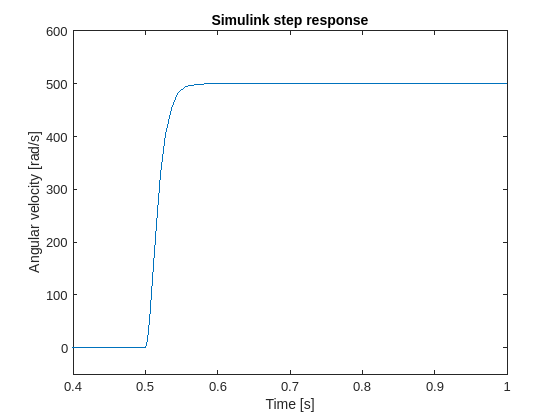

G_numerator = G.Numerator;
G_denominator = G.Denominator;

% The simulink model when run will write in this variable
out.step_response_simulink.plot;
ylabel("Angular velocity [rad/s]")
xlabel("Time [s]")
title("Simulink step response")

xlim([0.4 1.0])
ylim([-50 600])

This method also seems to indicate that a second order approximation is good.

### Note : We didn't use the *sim *function, however our method is analogous, its just using a "to workspace" block in simulink.

## c) Doing a local optimization with fminsearch.

Assuming that the transfer function is of the format $\frac{\mathit{\mathbf{k}}}{{\left(\mathit{\mathbf{s}}+{\mathit{\mathbf{p}}}_1 \right)}^2 }$ as done in point i), since its a second order system p1² = k.

As so the can define the cost function as a function of just 1 variable.

Defined in the end of this file

% Set the options for the fminsearch function
options = optimset('Display', 'iter');

x0 = 10;
% Run the optimization
params_opt = fminsearch(@(pole_pos) local_cost_function(pole_pos,data), x0, options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          20068.5         
     1            2          20068.5         initial simplex
     2            4          20065.1         expand
     3            7          20065.1         shrink
     4            9          20065.1         contract inside
     5           12          20065.1         shrink
     6           15          20065.1         shrink
     7           18          20065.1         shrink
     8           21          20065.1         shrink
     9           24          20065.1         shrink
    10           27          20065.1         shrink
    11           29          20065.1         contract inside
    12           32          20065.1         shrink
    13           35          20065.1         shrink
    14           38          20065.1         shrink
    15           41          20065.1         shrink
    16           43          20065.1         contract outside
 
Optimization terminated:
 

params_opt = 9.2500


s = tf('s');

G_fminsearch = params_opt^2/(s+params_opt)^2

G_fminsearch =
 
         85.56
  --------------------
  s^2 + 18.5 s + 85.56
 
Continuous-time transfer function.



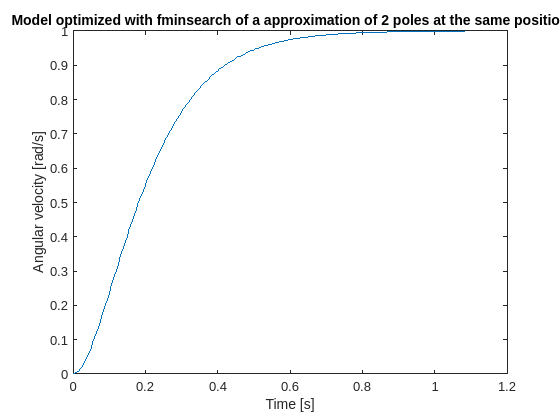

[y_fmin t_fmin] = step(G_fminsearch);

plot(t_fmin,y_fmin);
ylabel("Angular velocity [rad/s]")
xlabel("Time [s]")
title("Model optimized with fminsearch of a approximation of 2 poles at the same position")

The approximation results in a slower response, however we can still see the overall 2º order system behavior.

## d) Using GlobalSearch

% % Define the optimization variables
% args = optimvar('args', 3, 1);
% % Define the objective function
% objective = global_cost_function(args,data);
% 
% 
% % Create the optimization problem
% problem = optimproblem('Objective', objective);
% 
% % Create a GlobalSearch object
% gs = GlobalSearch;
% 
% % Solve the optimization problem
% [params_opt, cost_opt] = solve(gs, problem);




## b) Comparing results

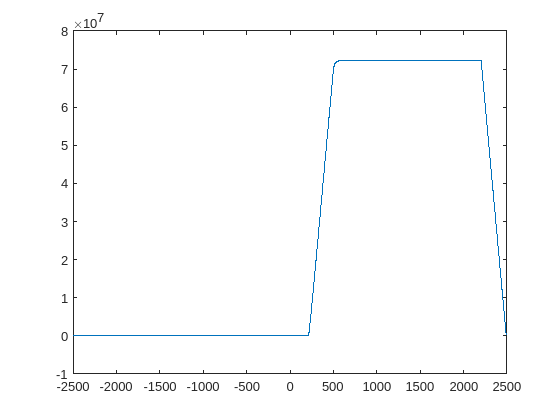

w_real_downsampled = w_real;
w_real_downsampled(time_data>0.8) = 500;

[acor,lag] = xcorr(w_real_downsampled,out.step_response_simulink.Data);
plot(lag,acor);

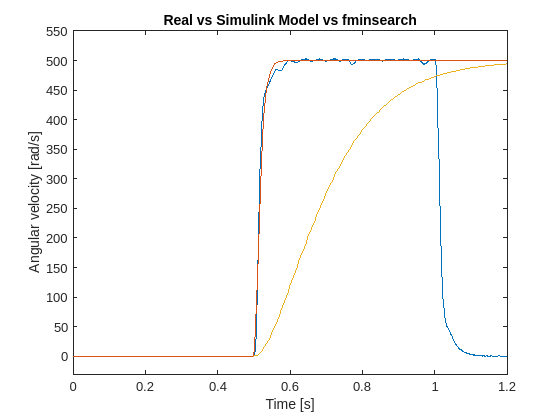


plot(time_data, w_real);
hold on
plot(out.tout,out.step_response_simulink.Data);
plot(t_fmin+0.5, 500*y_fmin);
xlim([0.000 1.2])
ylim([-30 550])
ylabel("Angular velocity [rad/s]")
xlabel("Time [s]")
title("Real vs Simulink Model vs fminsearch")


hold off;

The values given by xcorr aren't really good, I think its because the samples have vastly different sizes, because just by the graph its clear they're pretty similar.

function cost = local_cost_function(pole_pos,data)

    s = tf('s');

    G = pole_pos^2/(s+pole_pos)^2;
    
    num_of_points = length(data.X.Data);
    
    n = 100;

    %Downscaling data

    data.X.Data    = data.X.Data(1:floor(length(data.X.Data)/n):end);
    data.Y(3).Data = data.Y(3).Data(1:floor(length(data.Y(3).Data)/n):end);

    data.X.Data    = data.X.Data(1:100);
    data.Y(3).Data = data.Y(3).Data(1:100);

    [y,t] = step(G,data.X.Data(end)); % Up to data's seconds

    error = 0;
    for i=1:length(data.X.Data)
        
        error = error + sqrt( (data.Y(3).Data(i)- y(i)).^2);
    end
    cost = error;

end


function cost = global_cost_function(params,data)

    pole_pos1 = params(1)/2*2;
    pole_pos2 = params(2)/2*2;
    k         = params(3)/2*2;

    s = tf('s');

    G = k./((s+pole_pos1)*(s+pole_pos2));
     
    n = 100;

    %Downscaling data

    data.X.Data    = data.X.Data(1:floor(length(data.X.Data)/n):end);
    data.Y(3).Data = data.Y(3).Data(1:floor(length(data.Y(3).Data)/n):end);

    data.X.Data    = data.X.Data(1:100);
    data.Y(3).Data = data.Y(3).Data(1:100);

    [y,t] = step(G,data.X.Data(end)); % Up to data's seconds

    error = 0;
    for i=1:length(data.X.Data)
        
        error = error + sqrt( (data.Y(3).Data(i)- y(i)).^2);
    end
    cost = error;

end